# MSM semestrální práce

Jakub Znamenáček

clc
close all %zavře všechna okna
clearvars %smaže proměnné z workspace

## Zadání

Cílem této semestrální práce je analýza systému představovaného dvěma inverzními kyvadly spojenými pružinou. Na první kyvadlo dále působí síla od torzní pružiny $k_t$. Časově proměnný moment $M_t$ by pak měl sloužit k řízení polohy prvního kyvadla.

### Zadané hodnoty


$$m_1=5 \text{kg }, m_2 =2\text{kg }, a = 0,5\text{m },b=0,75\text{m }, c=1,25\text{m },d =1\text{m },k = 5800\text{N/m },k_t = 1100\text{Nm/rad }, b_1 =6,1\text{Ns }, b_2 =8,8\text{Ns }, g = 9,81\mathrm{m/s^2}\text{ },\varphi_{10}= 35°\text{ },\dot{\varphi}_{10}=0\text{rad/s },\varphi_{20}= 0°\text{ },\dot{\varphi}_{20}= 0\text{rad/s }$$


m1 = 5; %kg
m2 = 2; %kg
a = 0.5; %m
b = 0.75; %m
c = 1.25; %m
d = 1; %m
k = 5.8*100; %N/m
kt = 1.1*100; %Nm/rad
b1 = 6.1; %Ns
b2 = 8.8; %Ns
g = 9.81; %m/s2

phi10 = deg2rad(35); %rad
dphi10 = 0; %rad/s
phi20 = 0; %rad
dphi20 = 0; %rad/s

M_t = 0; %Nm

### Zjednodušený nákras zadaného systému

#### 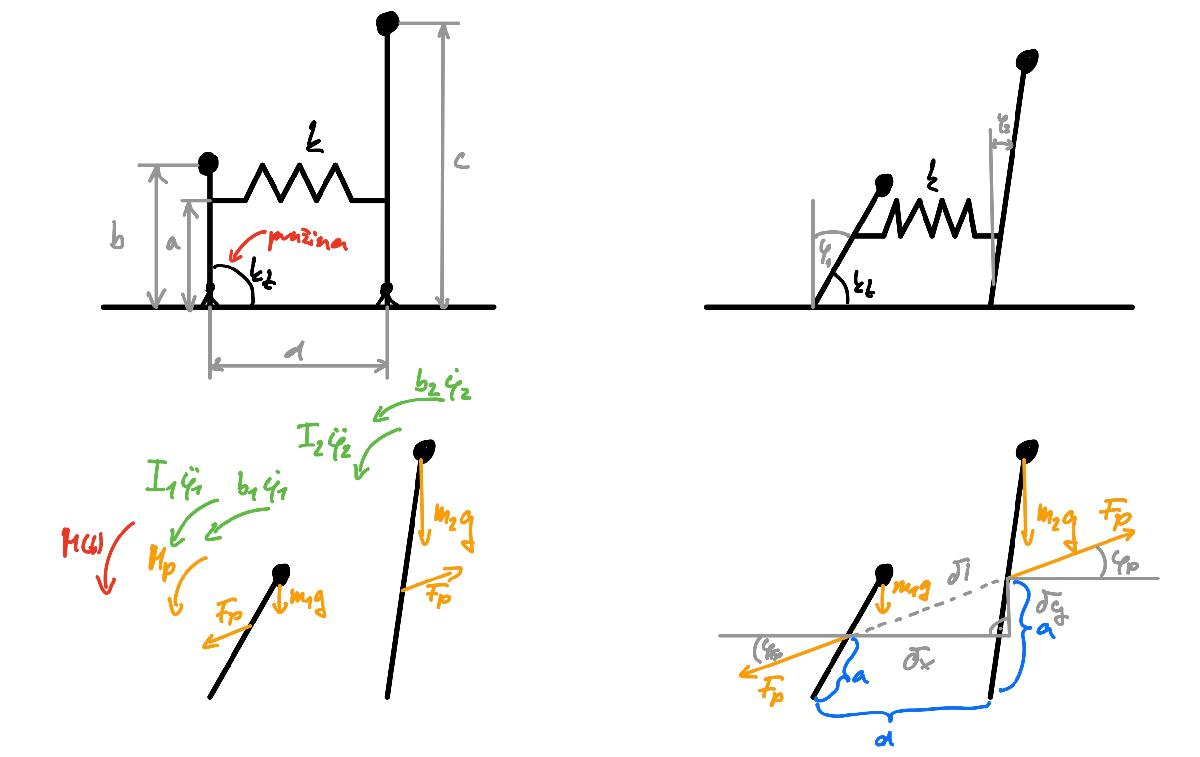

#### Dopočtené hodnoty


$$G_1 = m_1g, G_2=m_2g, I_1 = m_1b^2, I_2 = m_2c^2$$


G1 = m1*g %kgm/s2°

G1 = 49.0500

G2 = m2*g %kgm/s2

G2 = 19.6200

I1 = m1*b^2 %kg*m2

I1 = 2.8125

I2 = m2*c^2 %kg*m2

I2 = 3.1250


x10 = phi10; %rad
x20 = dphi10; %rad/s
x30 = phi20; %rad
x40 = dphi20; %rad/s
x0 = [x10,x20,x30,x40];

## Nelineární model

### Newton-Eulerovy pohybové rovnice


$$I_1\ddot\varphi_1=-M_p-b_1\dot\varphi_1-F_p\cos(\varphi_p)a\cos(\varphi_1)+G_1b\sin(\varphi_1)-M_t$$


$I_2\ddot\varphi_2 = -b_2\dot\varphi_2+F_p\cos(\varphi_p)a\cos(\varphi_2)+G_2b\sin(\varphi_2)$,

kde poměnná $F_p$ představuje sílu vyvolanou lineární pružinou a $\varphi_p$ úhel působení této síly.

### Stavový popis

Stavové proměnné jsou $x_1 =\varphi_1$, $x_2 =\dot{ \varphi}_1$, $x_3 = \varphi_2$, $x_4 = \dot{\varphi}_2$ reprezentující úhel a rychlost prvního a druhého inverzního kyvadla. Metodou snižování řádu diferenciální rovnice získáme následující stavové rovnice nelineárního systému.


$$\dot x_1=x_2$$



$$\dot x_2 =\frac {-x_1k_t - b_1x_2-k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_1)+G_1b\sin(x_1)-M_t} {I_1}$$



$$\dot x_3 =x_4$$



$$\dot x_4 = \frac {-b_2x_4+k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_3)+G_2c\sin(x_3)}{I_2}$$


### Nastavení simulace

Pomocí táhla lze nastavit délku času simulace nelineárního modelu v symulinku ideální hodnotou je 5 s.

tmax=5;%s - maximální čas simulace


### Výpočet pomocí simuliku

Stisknutím tlačítka "spustit simulink" proběhne výpočet polohových úhlů $\varphi_1$ a $\varphi_2$.

simulinkTempNelinearni = sim('NELINEARIZOVANEsimulink.slx',tmax); % načtení simulinku
phi1 = simulinkTempNelinearni.x1; % uložení výstupu simulinku do proměnné
phi2 = simulinkTempNelinearni.x3; % uložení výstupu simulinku do proměnné
Fp_simulink = simulinkTempNelinearni.Fp; % uložení výstupu simulinku do proměnné

### Graf závislosti $\varphi_1$ a $\varphi_2$ na čase

Následující graf představuje průběh pohybu inverzních kyvadel z počáteční polohy $\varphi_{10}= 35°\text{ },\dot{\varphi}_{10}=0\text{ rad/s },\varphi_{20}= 0°\text{ },\dot{\varphi}_{20}= 0\text{ rad/s }$ do ustáleného stavu bez jakéhokoli vnějšího působení na systém.

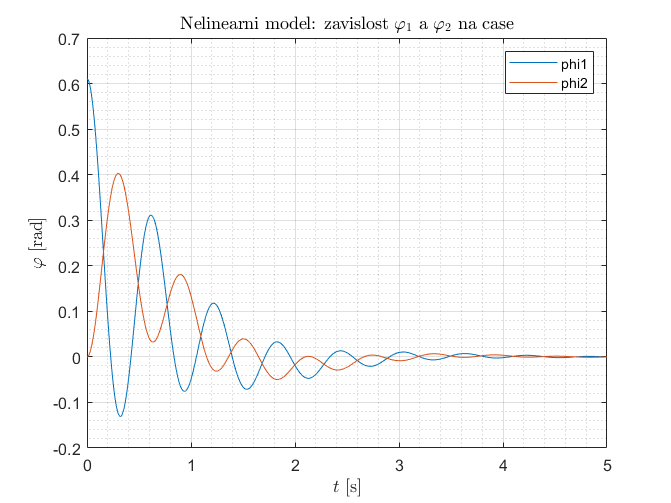

figure
plot(phi1)
hold on %podrží graf na obrazovce, aby mohl být přidán další
plot(phi2)
grid on %zapne mřížku grafu
grid minor %zapne přesnější mřížku
title('Nelinearni model: zavislost $$\varphi_1$$ a $$\varphi_2$$ na case','Interpreter','latex') %nadpis grafu
xlabel('$t$ [s]','Interpreter','latex') %popis osy x
ylabel('$\varphi$ [rad]','Interpreter','latex') %popis osy y
legend({'phi1','phi2'},'Location','northeast') %legenda grafu

### Animace

Animace pohybu kyvadel vypočtená z nelineárního modelu pomocí simulinku. Pružina je znázorněna úsečkou spojující obě inverzní kyvadla. Barva úsečky je závislá na působení síly a to tak, že pokud jsou kyvadla odtlačována od sebe je barva úsečky červené a naopak pokud na ně působí síla vyvolaná pružinou tak, že jsou přitahována k sobě, tak je barva zelená.

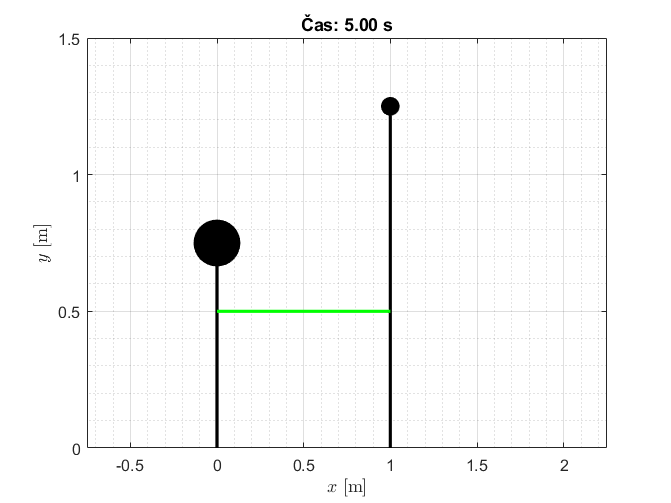


%close all
figure
%plot(0,0)
%grid on


for i = 1:length(phi1.Data)
    cla
    
    %kyvadlo 1
    plot([0 b*sin(phi1.Data(i))],[0 b*cos(phi1.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 1 tyč
    hold on
    plot(b*sin(phi1.Data(i)),b*cos(phi1.Data(i)),'MarkerSize',m1*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 1 závaží
    
    %kyvadlo 2 
    hold on
    plot(d+[0 c*sin(phi2.Data(i))],[0 c*cos(phi2.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 2 tyč
    hold on
    plot(d+c*sin(phi2.Data(i)),c*cos(phi2.Data(i)),'MarkerSize',m2*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 2 závaží
    
    %pružina
    hold on
    if(Fp_simulink.Data(i)>0)
        plot([a*sin(phi1.Data(i)) (d+a*sin(phi2.Data(i)))],[a*cos(phi1.Data(i)) a*cos(phi2.Data(i))],'LineWidth',2,"Color",[1 0 0]) % kyvadlo 1 tyč
    else
        plot([a*sin(phi1.Data(i)) (d+a*sin(phi2.Data(i)))],[a*cos(phi1.Data(i)) a*cos(phi2.Data(i))],'LineWidth',2,"Color",[0 1 0]) % kyvadlo 1 tyč
    end
    
    
    %nastavení rozsahů os
    xlim([-b (d+c)])
    ylim([0 c*1.2])
    
    
    
    %popis grafu
    title(['Čas: ',num2str(phi1.Time(i),'%1.2f'),' s']) %nadpis grafu
    xlabel('$x$ [m]','Interpreter','latex') %popis osy x
    ylabel('$y$ [m]','Interpreter','latex') %popis osy y
    grid on %zapne mřížku grafu
    grid minor %zapne přesnější mřížku
    
    %nastavení rychlosti animace
    pause(.0001)
    %zobrazení reálného času
    %legend(,'Location','northeast') %legenda grafu
end

## Lineární model

### Linearizace

%definice symbolických proměnných
syms x1;
syms x2;
syms x3;
syms x4;

syms Mt; %Nm

%odkomentovat pro kontrolu rovnic
%{
syms a; %m
syms b; %m
syms c; %m
syms d; %m
syms k; %N/m
syms kt; %Nm/rad
syms b1; %Ns
syms b2; %Ns
syms g; %m/s2
syms G1; %kgm/s2°
syms G2; %kgm/s2
syms I1; %kg*m2
syms I2; %kg*m2
%}

#### Stavový popis

Obdobně jako u nelineárního systému jsou stavové proměnné $x_1 =\varphi_1$, $x_2 =\dot{ \varphi}_1$, $x_3 = \varphi_2$, $x_4 = \dot{\varphi}_2$ reprezentující úhel a rychlost prvního a druhého inverzního kyvadla. Pro jednoduší práci s výpočty byly zavedeny následující pomocné proměnné, které jsou znázorněny na náčrtku.

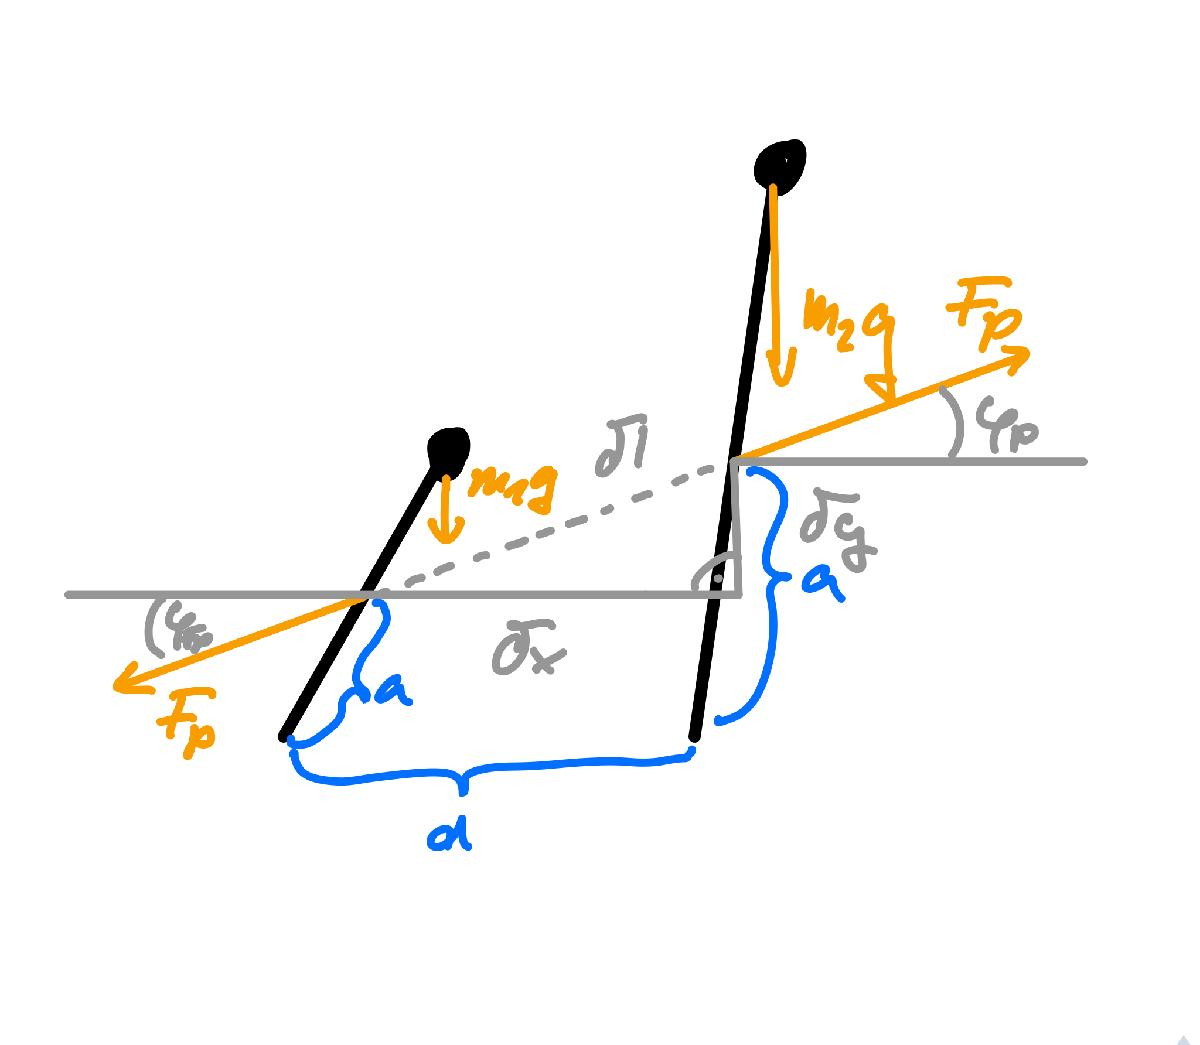


$$\delta_x = d-a\left(sin(x_1)-sin(x_3)\right)$$



$$\delta_y = a\left( cos(x_3)-cos(x_1)\right)$$



$$\Delta l = d - \delta _l=d-\sqrt{\delta_x^2+\delta_y^2}$$



$$F_p =k\Delta l$$



$$\varphi_p = \arctan\left(\frac{\delta_y}{\delta_x}\right)$$


%pomocné výpočty
deltax = d-a*(sin(x1)-sin(x3));
deltay = a*(cos(x3)-cos(x1));
DELTAl = d-sqrt(deltax^2+deltay^2);
Fp = k*DELTAl;
phip = atan(deltay/deltax);

Pro přehlednost jsou zde ještě jednou zobrazeny stavové rovnice nelineárního systému $f_1$ až $f_4$.


$$\dot x_1=f_1=x_2$$



$$\dot x_2 =f_2=\frac {-x_1k_t - b_1x_2-k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_1)+G_1b\sin(x_1)-M_t} {I_1}$$



$$\dot x_3=f_3 =x_4$$



$$\dot x_4 =f_4= \frac {-b_2x_4+k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_3)+G_2c\sin(x_3)}{I_2}$$


%stavové rovnice
f1 = x2;
f2 =(-x1*kt -b1*x2-Fp*cos(phip)*a*cos(x1)+G1*b*sin(x1)-Mt)/I1;
f3 =x4;
f4 =(-b2*x4 +Fp*cos(phip)*a*cos(x3)+G2*c*sin(x3))/I2;

#### Singulární body

Nelineární systém může mít $0$ až $\infty$ singulárních bodů. Pro jednotlivé singulární body musí platit nádledující rovnice $\dot{\it{\bf{x}}}=0$, ${\it{\bf{u}}}={\it{\bf{u_s}}} =\text{konst.}$ (v našem případě ${\it{\bf{u_s}}} = M_t=0$). První rovnici lze též zapsat jako ${\it{\bf{f}}(x_s,u_x)} ={\it{\bf{0}}}$. Hledáme tak řešení splňující následující soustavu rovnic.


$$0=x_2$$



$$0=\frac {-x_1k_t - b_1x_2-k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_1)+G_1b\sin(x_1)-M_t} {I_1}$$



$$0 =x_4$$



$$0= \frac {-b_2x_4+k\left(d-\sqrt{(d-a(\sin(x_1)-\sin(x_3))^2+(a(\cos(x_3)-\cos(x_1)))^2}\right)\cos(\arctan\left(\frac{a\left(\cos(x_3)-\cos(x_1)\right)}{d-a\left(\sin(x_1)-\sin(x_3)\right)}\right)a\cos(x_3)+G_2c\sin(x_3)}{I_2}$$


Z výše zmíněných rovnic na první pohled vyplývá řešení pro $x_2$ a $x_4$, zbývá tak nalézt řešení pro zbývající $x_1$ a $x_3$. Toto řešení bohužel nebylo možné řešit symbolicky a tak bylo přistoupeno k numerickému řešení.

%definice symbolických proměnných
%syms x1s;
%syms x2s;
%syms x3s;
%syms x4s;

%hledání singulárních bodů
%[x1s,x2s,x3s,x4s] = solve([0 == x2s,0 == (-x1s*kt -b1*x2s-Fp*cos(phip)*a*cos(x1s)+G1*b*sin(x1s)-Mt)/I1, 0 == x4s,0 == (-b2*x4 +Fp*cos(phip)*a*cos(x3s)+G2*c*sin(x3s))/I2],...
%[x1s,x2s,x3s,x4s]);
%[x1s] = solve([sin(x1s) ==phi10],[x1s])


#### Numerické řešení singulárních bodů

Pomocí numerické metody lze zavedením pomocné funkce "stavovaRovnice" hledat řešení v blízkosti daného bodu. Jelikož nás nejvíce zajímá okolí bodu ${\it{\bf{x}}}=\left[ \begin{array}{rrr}0 \\ 0 \\0 \\0\\ \end{array}\right]$ budeme hledat numerické řešení rovice ${\it{\bf{f}}(x_s,u_x)} ={\it{\bf{0}}}$ v blízkosti námi zvoleného bodu $z_g$

zg= [0.1;0.1;0.1;0.1]

zg =     0.1000
    0.1000
    0.1000
    0.1000


z =fsolve(@stavovaRovnice,zg)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


z = 	1.0e+-9 *

   -0.1107
    0.0000
   -0.2914
         0


Jak je patrné z výsledku, jedním ze singulárních bodů by mohl být bod  ${\it{\bf{x_s}}}=\left[ \begin{array}{rrr}0 \\ 0 \\0 \\0\\ \end{array}\right]$, který nás i nejvíce zajímá, neb mechanizmus bude pracovat v jeho okolí. Ověřme tedy, že opravdu splňuje rovnici ${\it{\bf{f}}}=0$

xs = [0 0 0 0]; %singulární bod
Mts = 0;
x = [x1 x2 x3 x4]; %vektor stavových proměnných

subs(f1, cat(2, x,Mt), cat(2, xs,Mts)) %cat(2, xs,Mts) je spojení polí

$$ans = 0$$

subs(f2, cat(2, x,Mt), cat(2, xs,Mts))

$$ans = 0$$

subs(f3, cat(2, x,Mt), cat(2, xs,Mts))

$$ans = 0$$

subs(f4, cat(2, x,Mt), cat(2, xs,Mts))

$$ans = 0$$

vidíme,  že ${\it{\bf{x_s}}}=\left[ \begin{array}{rrr}0 \\ 0 \\0 \\0\\ \end{array}\right]$splňuje rovnici ${\it{\bf{f}}}={\it{\bf{0}}}$. Linearizaci  systému tedy provedeme v tomto singulárním bodě stavového prostoru. Linearizaci lze provést podle následující rovnice.


$${\it{\bf{f}}} ({\it{\bf{x}}}(t),{\it{\bf{u}}}(t))= {\it{\bf{f}}} ({\it{\bf{x_s}}},{\it{\bf{u_s}}})+\frac{\partial{\it{\bf{f}}}}{\partial{\it{\bf{x_s}}}} \bigg|_{S}({\it{\bf{x}}}(t)-{\it{\bf{x_s}}})+\frac{\partial{\it{\bf{f}}}}{\partial{\it{\bf{u}}}} \bigg|_{S}({\it{\bf{u}}}(t)-{\it{\bf{u_s}}})
$$


vzhledem k tomu, že ${\it{\bf{x_s}}}$, ${\it{\bf{u_s}}}$ a ${\it{\bf{f}}} ({\it{\bf{x_s}}},{\it{\bf{u_s}}})$ jsou rovny nule, zjednoduší se nám linearizované stavové rovnice systému na následující rovnici.


$${\it{\bf{f}}} ({\it{\bf{x}}}(t),{\it{\bf{u}}}(t))= \frac{\partial{\it{\bf{f}}}}{\partial{\it{\bf{x_s}}}} \bigg|_{S}{\it{\bf{x}}}(t)+\frac{\partial{\it{\bf{f}}}}{\partial{\it{\bf{u}}}} \bigg|_{S}{\it{\bf{u}}}(t)
$$


#### Linearizované stavové rovnice v singulárním bodě ${\it{\bf{x_s}}}={{\bf{0}}}$

%linearizované stavové rovnice
f1_lin = subs(diff(f1,x1), x, xs)*(x1-xs(1)) + subs(diff(f1,x2), x, xs)*(x2-xs(2)) ...
       + subs(diff(f1,x3), x, xs)*(x3-xs(3)) + subs(diff(f1,x4), x, xs)*(x4-xs(4)) + subs(diff(f1,Mt), Mt, Mts)*(Mt-Mts)

$$f1\_lin = x_{2}$$

f2_lin = subs(diff(f2,x1), x, xs)*(x1-xs(1)) + subs(diff(f2,x2), x, xs)*(x2-xs(2)) ...
       + subs(diff(f2,x3), x, xs)*(x3-xs(3)) + subs(diff(f2,x4), x, xs)*(x4-xs(4)) + subs(diff(f2,Mt), Mt, Mts)*(Mt-Mts)

$$f2\_lin = \frac{464\,x_{3}}{9}-\frac{5819\,x_{1}}{75}-\frac{488\,x_{2}}{225}-\frac{16\,\mathrm{Mt}}{45}$$

f3_lin = subs(diff(f3,x1), x, xs)*(x1-xs(1)) + subs(diff(f3,x2), x, xs)*(x2-xs(2)) ...
       + subs(diff(f3,x3), x, xs)*(x3-xs(3)) + subs(diff(f3,x4), x, xs)*(x4-xs(4)) + subs(diff(f3,Mt), Mt, Mts)*(Mt-Mts)

$$f3\_lin = x_{4}$$

f4_lin = subs(diff(f4,x1), x, xs)*(x1-xs(1)) + subs(diff(f4,x2), x, xs)*(x2-xs(2)) ...
       + subs(diff(f4,x3), x, xs)*(x3-xs(3)) + subs(diff(f4,x4), x, xs)*(x4-xs(4)) + subs(diff(f4,Mt), Mt, Mts)*(Mt-Mts)

$$f4\_lin = \frac{232\,x_{1}}{5}-\frac{4819\,x_{3}}{125}-\frac{352\,x_{4}}{125}$$

#### Maticový zápis

Linearizované stavové rovnice lze též zapistovat v maticovém tvaru ${\it{\bf{\dot x}}}= {\it{\bf{Ax}}} + {\it{\bf{Bu}}}$, ${\it{\bf{y}}}= {\it{\bf{Cx}}} + {\it{\bf{Du}}}$, který následně usnadní další práci se systémem. Matice ${\it{\bf{A}}},{\it{\bf{B}}},{\it{\bf{C}}},{\it{\bf{D}}}$ v tomto zápise pak mají následující podobu.

A = [subs(diff(f1,x1), x, xs) subs(diff(f1,x2), x, xs) subs(diff(f1,x3), x, xs) subs(diff(f1,x4), x, xs);
     subs(diff(f2,x1), x, xs) subs(diff(f2,x2), x, xs) subs(diff(f2,x3), x, xs) subs(diff(f2,x4), x, xs);
     subs(diff(f3,x1), x, xs) subs(diff(f3,x2), x, xs) subs(diff(f3,x3), x, xs) subs(diff(f3,x4), x, xs);
     subs(diff(f4,x1), x, xs) subs(diff(f4,x2), x, xs) subs(diff(f4,x3), x, xs) subs(diff(f4,x4), x, xs)]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{5819}{75} & -\frac{488}{225} & \frac{464}{9} & 0\\ 0 & 0 & 0 & 1\\ \frac{232}{5} & 0 & -\frac{4819}{125} & -\frac{352}{125} \end{array}\right)$$

B = [subs(diff(f1,Mt), Mt, Mts);
     subs(diff(f2,Mt), Mt, Mts);
     subs(diff(f3,Mt), Mt, Mts);
     subs(diff(f4,Mt), Mt, Mts)]

$$B = \left(\begin{array}{c} 0\\ -\frac{16}{45}\\ 0\\ 0 \end{array}\right)$$

C = [1 0 0 0; 0 0 1 sym(0)] %%sym(0) jen aby matlab matici vypsal hezky v live scriptu

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

 D = [0 ;sym(0)]

$$D = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

 %převod symbolických matic na numerické
 An = double(A);
 Bn = double(B);
 Cn = double(C);
 Dn = double(D);

 

#### Nastavení simulace

Pomocí táhla lze obdobně jako u nelineárního systému nastavit délku času simulace nelineárního modelu v symulinku i zde je ideální hodnotou je 5 s.

tmax=5;%s - maximální čas simulace

#### Výpočet pomocí simuliku

Stisknutím tlačítka "spustit simulink" proběhne výpočet polohových úhlů $\varphi_1$ a $\varphi_2$.

simulinkTemp = sim('LINEARIZOVANEsimulink.slx',tmax);
phi1_lin = simulinkTemp.x1;
phi2_lin = simulinkTemp.x3;

#### Graf závislosti $\varphi_1$ a $\varphi_2$ na čase

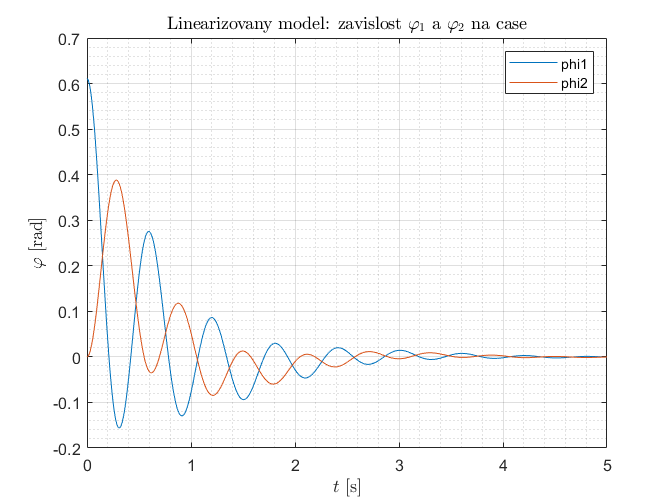

figure
plot(phi1_lin)
hold on %podrží graf na obrazovce, aby mohl být přidán další
plot(phi2_lin)
grid on %zapne mřížku grafu
grid minor %zapne přesnější mřížku
title('Linearizovany model: zavislost $$\varphi_1$$ a $$\varphi_2$$ na case','Interpreter','latex') %nadpis grafu
xlabel('$t$ [s]','Interpreter','latex') %popis osy x
ylabel('$\varphi$ [rad]','Interpreter','latex') %popis osy y
legend({'phi1','phi2'},'Location','northeast') %legenda grafu

#### Animace

Stejně jako u nelinearizovaného modelu je zde zobrazena animace pohybu kyvadel. Pružina je opět znázorněna úsečkou spojující obě inverzní kyvadla, jejíž barva opět závisí na směru působení síly.

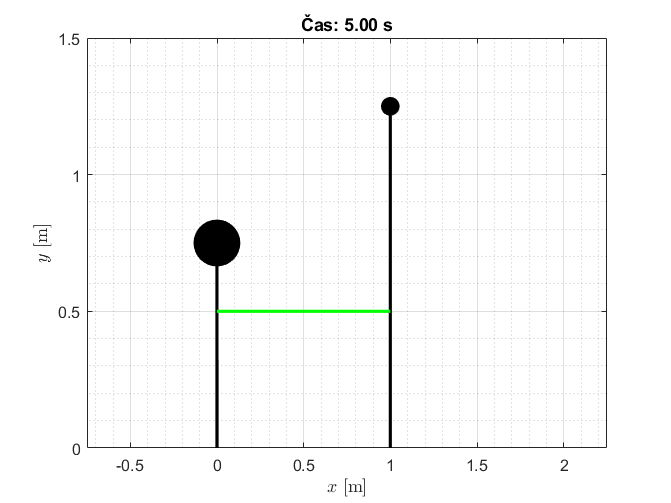



figure


for i = 1:length(phi1_lin.Data)
    cla
    
    %kyvadlo 1
    plot([0 b*sin(phi1_lin.Data(i))],[0 b*cos(phi1_lin.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 1 tyč
    hold on
    plot(b*sin(phi1_lin.Data(i)),b*cos(phi1_lin.Data(i)),'MarkerSize',m1*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 1 závaží
    
    %kyvadlo 2 
    hold on
    plot(d+[0 c*sin(phi2_lin.Data(i))],[0 c*cos(phi2_lin.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 2 tyč
    hold on
    plot(d+c*sin(phi2_lin.Data(i)),c*cos(phi2_lin.Data(i)),'MarkerSize',m2*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 2 závaží
    
    %pružina
    hold on
    if(phi1_lin.Data(i)>phi2_lin.Data(i)) %NUTNO ZKONTROLOVAT
        plot([a*sin(phi1_lin.Data(i)) (d+a*sin(phi2_lin.Data(i)))],[a*cos(phi1_lin.Data(i)) a*cos(phi2_lin.Data(i))],'LineWidth',2,"Color",[1 0 0]) % kyvadlo 1 tyč
    else
        plot([a*sin(phi1_lin.Data(i)) (d+a*sin(phi2_lin.Data(i)))],[a*cos(phi1_lin.Data(i)) a*cos(phi2_lin.Data(i))],'LineWidth',2,"Color",[0 1 0]) % kyvadlo 1 tyč
    end
    
    
    %nastavení rozsahů os
    xlim([-b (d+c)])
    ylim([0 c*1.2])
    
    
    
    %popis grafu
    title(['Čas: ',num2str(phi1_lin.Time(i),'%1.2f'),' s']) %nadpis grafu
    xlabel('$x$ [m]','Interpreter','latex') %popis osy x
    ylabel('$y$ [m]','Interpreter','latex') %popis osy y
    grid on %zapne mřížku grafu
    grid minor %zapne přesnější mřížku
    
    %nastavení rychlosti animace
    pause(.0001)
end

#### Graf rozdílu mezi linearizovaným a nelinearizovaným modelem

Na následujícím grafu je znázorněn průběh  $\varphi_{1 nelin.} -\varphi_{1lin.}$ a $\varphi_{2 nelin.} -\varphi_{2lin.}$. Jak je patrné, k největší maximální odchylce od nelineárního modelu řešeného přimo pomocí simulinku dochází v oblasti mezi první a druhou sekundou pohybu. Toto je dáno tím, že obě kyvadla ze začátku pohybu nabývají největších vychýlení, které se dále díky tlumení zmenšují. V oblasti kolem singulárního bodu systému (na grafu například oblast mezi čtvrtou a pátou sekundou pohybu) jsou odchylky od nelineárního modelu blízké nule. 

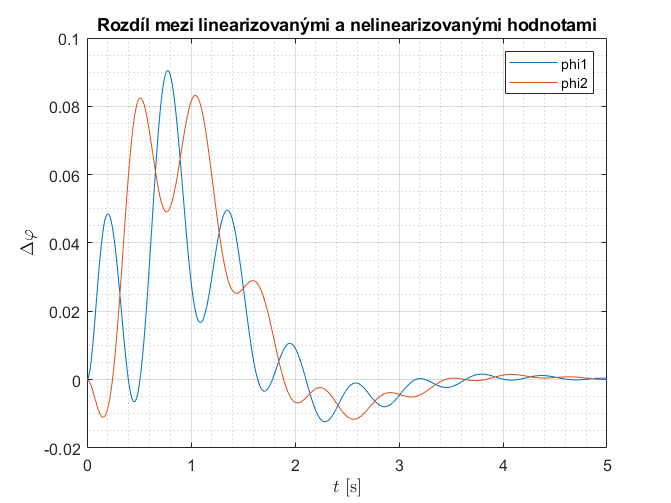

if (length(phi1.Data)==length(phi1_lin.Data)) %% zkontroluje, že data mají stejnou velikost
    figure
    plot(phi1-phi1_lin)
    hold on %podrží graf na obrazovce, aby mohl být přidán další
    plot(phi2-phi2_lin)
    grid on %zapne mřížku grafu
    grid minor %zapne přesnější mřížku
    title('Rozdíl mezi linearizovanými a nelinearizovanými hodnotami') %nadpis grafu
    xlabel('$t$ [s]','Interpreter','latex') %popis osy x
    ylabel('$\Delta\varphi$','Interpreter','latex') %popis osy y
    legend({'phi1','phi2'},'Location','northeast') %legenda grafu 
end

#### Stabilita  linearizovaného systému

Stabilita systému je dána vlastními čísly matice $\bf{A}$. Ta musí ležet na levé polorovině komplexní roviny, tedy jejich reálná část musí být záporná. Hodnoty vlastních čísel matice $\bf{A}$ linearizovaného systému jsou následující.

eig(An)

ans =   -1.1851 +10.4513i
  -1.1851 -10.4513i
  -1.3073 + 1.9247i
  -1.3073 - 1.9247i


Jak je patrné, je tato podmínka je splněna a jelikož je linearizovaný systém v bodu rovnováhy stabilní je podle Ljapunovovy první věty v tomto bodě stabilní i původní nelineární systém. 

## Návrh regulátoru

### Stavový regulátor pro regulaci do polohy $\varphi_1 = 0$

Stavový regulátor má v tomto případě za úkol regulovat systém tak aby dospěl do $\varphi_1=0$ požadovaným způsobem. Tento nový systém si lze představit jako puvodní systém, kde vstup $\bf{u_{r0}}$ je roven $-\bf{K_{r0}}\bf{x_{r0}}$.

#### Výběr požadovaných pólů a výpočet matice **K stavového regulátoru**

Systém s regulátorem by měl být stabilní s nekmitavou dynamikou. Stabilita systému je dána polohou pólů (vlastních čísel) matice $\bf{A_{r0}}$, které se musí nacházet na levé polorovině komplexní roviny. Jinak řečeno, jejich reálná složka musí být záporná. Nekmitavou dynamiku pak představují póly ryze reálné, tedy bez imaginární složky. Zvolíme tedy například následující póly.

%požadované
p1 = -10

p1 = -10

p2 = -8

p2 = -8

p3 = -11

p3 = -11

p4 = -9

p4 = -9

Nové matice systému $\bf{A_{r0}}$, $\bf{B_{r0}}$, $\bf{C_{r0}}$, $\bf{D_{r0}}$ lze spočítat jako $\bf{A_{r0}}=\bf{A}-\bf{BK_{r0}}$, $\bf{B_{r0}}=\bf{0}$, $\bf{C_{r0}}$ a $\bf{D_{r0}}$ volíme stejné jako u původního systému. 

p_desired_r0 = [p1 p2 p3 p4];
[Kr0]=place(An,Bn,p_desired_r0);
%symbolické jen kvůli vzhladu
Ar0 = A-B*Kr0

$$Ar0 = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ -\frac{24823733833719203}{61847529062400} & -\frac{34816695400495867}{989560464998400} & \frac{1006836544361443}{6184752906240} & -\frac{7637776723540069}{395824185999360}\\ 0 & 0 & 0 & 1\\ \frac{232}{5} & 0 & -\frac{4819}{125} & -\frac{352}{125} \end{array}\right)$$

Br0 = [0;0;0;sym(0)]

$$Br0 = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Cr0 = C

$$Cr0 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 \end{array}\right)$$

Dr0 = D

$$Dr0 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

%numerické
Ar0 = double(Ar0);
Br0 = double(Br0);
Cr0 = double(Cr0);
Dr0 = double(Dr0);

Vlastní čísla nové matice $\bf{A_{r0}}$ by tedy měli být schodné s požadovanými. Což jak vidíme platí.

vlastni_cisla_Ar0 = eig(Ar0)

vlastni_cisla_Ar0 =   -11.0000
  -10.0000
   -9.0000
   -8.0000


#### Nastavení simulace

Pomocí táhla lze nastavit délku času simulace nelineárního modelu v symulinku ideální hodnotou je 5 s.

tmax=5;%s - maximální čas simulace


#### Výpočet pomocí simuliku

Stisknutím tlačítka "spustit simulink" proběhne výpočet polohových úhlů $\varphi_1$ a $\varphi_2$.

 
simulinkTemp = sim('REG0_LINEARIZOVANE_simulink.slx',tmax);
phi1_lin_r0 = simulinkTemp.x1r0;
phi2_lin_r0 = simulinkTemp.x3r0;

#### Graf závislosti $\varphi_1$ a $\varphi_2$ na čase pro regulovaný a neregulovaný systém

Jak je patrné z následujících grafů, linearizovaný systém regulovaný pomocí stavového regulátoru dospěje ze stejných počátečních podmínek do rovnovážného stavu do jedné a půl sekundy, kdežto neregulovaný linearizovaný systém až za pět sekund, což je více než třikrát pomaleji.

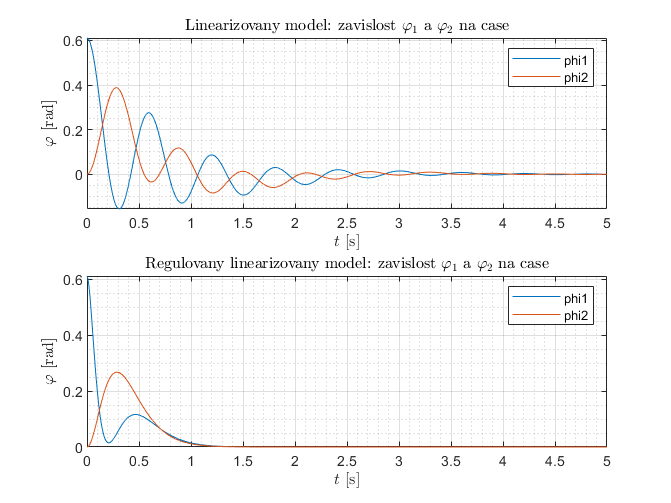

figure

%linearizovaný neregulovaný
subplot(2,1,1)
plot(phi1_lin)
hold on %podrží graf na obrazovce, aby mohl být přidán další
plot(phi2_lin)
grid on %zapne mřížku grafu
grid minor %zapne přesnější mřížku
title('Linearizovany model: zavislost $$\varphi_1$$ a $$\varphi_2$$ na case','Interpreter','latex') %nadpis grafu
xlabel('$t$ [s]','Interpreter','latex') %popis osy x
ylabel('$\varphi$ [rad]','Interpreter','latex') %popis osy y
legend({'phi1','phi2'},'Location','northeast') %legenda grafu

%regulovaný
subplot(2,1,2)
plot(phi1_lin_r0)
hold on %podrží graf na obrazovce, aby mohl být přidán další
plot(phi2_lin_r0)
grid on %zapne mřížku grafu
grid minor %zapne přesnější mřížku
title('Regulovany linearizovany model: zavislost $$\varphi_1$$ a $$\varphi_2$$ na case','Interpreter','latex') %nadpis grafu
xlabel('$t$ [s]','Interpreter','latex') %popis osy x
ylabel('$\varphi$ [rad]','Interpreter','latex') %popis osy y
legend({'phi1','phi2'},'Location','northeast') %legenda grafu

#### Animace

Pomocí tlačítka "Spustit animaci" se spustí animace pohybu kyvadel regulovaného linearizovaného systému. Pružina je znázorněna úsečkou spojující obě inverzní kyvadla. Barva úsečky představující pružinu závisí na působení síly, kteru pružina vyvolává.

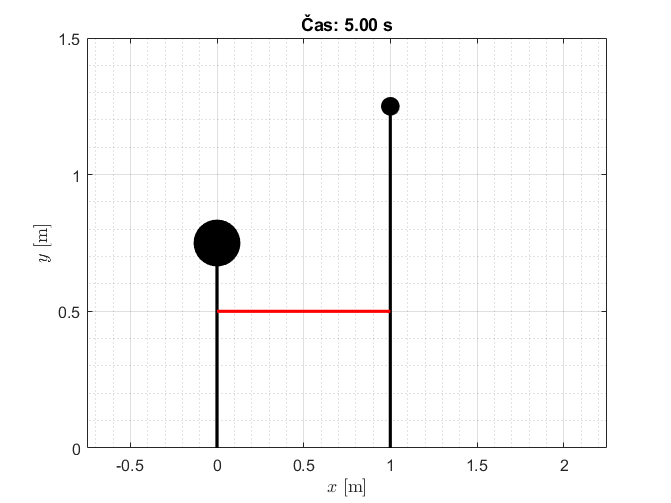


%close all
figure
%plot(0,0)
%grid on


for i = 1:length(phi1_lin_r0.Data)
    cla
    
    %kyvadlo 1
    plot([0 b*sin(phi1_lin_r0.Data(i))],[0 b*cos(phi1_lin_r0.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 1 tyč
    hold on
    plot(b*sin(phi1_lin_r0.Data(i)),b*cos(phi1_lin_r0.Data(i)),'MarkerSize',m1*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 1 závaží
    
    %kyvadlo 2 
    hold on
    plot(d+[0 c*sin(phi2_lin_r0.Data(i))],[0 c*cos(phi2_lin_r0.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 2 tyč
    hold on
    plot(d+c*sin(phi2_lin_r0.Data(i)),c*cos(phi2_lin_r0.Data(i)),'MarkerSize',m2*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 2 závaží
    
    %pružina
    hold on
    if((phi1_lin_r0.Data(i)-phi2_lin_r0.Data(i))>=0)
        plot([a*sin(phi1_lin_r0.Data(i)) (d+a*sin(phi2_lin_r0.Data(i)))],[a*cos(phi1_lin_r0.Data(i)) a*cos(phi2_lin_r0.Data(i))],'LineWidth',2,"Color",[1 0 0]) % kyvadlo 1 tyč
    else
        plot([a*sin(phi1_lin_r0.Data(i)) (d+a*sin(phi2_lin_r0.Data(i)))],[a*cos(phi1_lin_r0.Data(i)) a*cos(phi2_lin_r0.Data(i))],'LineWidth',2,"Color",[0 1 0]) % kyvadlo 1 tyč
    end
    
    
    %nastavení rozsahů os
    xlim([-b (d+c)])
    ylim([0 c*1.2])
    
    
    
    %popis grafu
    title(['Čas: ',num2str(phi1.Time(i),'%1.2f'),' s']) %nadpis grafu
    xlabel('$x$ [m]','Interpreter','latex') %popis osy x
    ylabel('$y$ [m]','Interpreter','latex') %popis osy y
    grid on %zapne mřížku grafu
    grid minor %zapne přesnější mřížku
    
    %nastavení rychlosti animace
    pause(.0001)
    %zobrazení reálného času
    %legend(,'Location','northeast') %legenda grafu
end

### Stavový regulator pro regulaci na požadovaný úhel

Stavový regulátor má v tomto případě za úkol regulovat systém tak, aby dospěl do zboleného $\varphi_{1k}$ požadovaným způsobem.

#### Výběr požadovaných pólů a výpočet matice K stavového regulátoru

Podobně jako v případě kdy systém měl dospět do $\varphi_1 =0$ i zde má mít systém s regulátorem stabilní a nekmitavou dynamiku. Stabilita systému je opět dána polohou pólů (vlastních čísel) matice $\bf{A_{rx}}$. Jelikož se v tomto případě jedná o stavový regulátor, u něž lze volit požadovaná hodnota, zvýší se řád systému o jedna. Voleny jsou tedy následující vlastní čísla.

%volba pólů systému s regulátorem
p1_rx = -6

p1_rx = -6

p2_rx = -8

p2_rx = -8

p3_rx = -5

p3_rx = -5

p4_rx = -9

p4_rx = -9

p5_rx = -7

p5_rx = -7

Nové matice systému $\bf{A_{rx}}$, $\bf{B_{rx}}$, $\bf{C_{rx}}$, $\bf{D_{rx}}$ mají následující podobu. 

%symbolické kvůli vzhledu
Arx = [A [0;0;0;0];
       -1 0 0 0 0]

$$Arx = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ -\frac{5819}{75} & -\frac{488}{225} & \frac{464}{9} & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ \frac{232}{5} & 0 & -\frac{4819}{125} & -\frac{352}{125} & 0\\ -1 & 0 & 0 & 0 & 0 \end{array}\right)$$

Brx = [B;0]

$$Brx = \left(\begin{array}{c} 0\\ -\frac{16}{45}\\ 0\\ 0\\ 0 \end{array}\right)$$

Crx = [1,0,0,0,0;
       0,0,1,0,sym(0)]

$$Crx = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 \end{array}\right)$$

Drx = [0;sym(0)]

$$Drx = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


%numerické
Arx = double(Arx);
Brx = double(Brx);
Crx = double(Crx);
Drx = double(Drx);

%počáteční podmíky
x0rx = [x0,0];
p_desired_rx = [p1_rx p2_rx p3_rx p4_rx p5_rx];
[Krx]=place(Arx,Brx,p_desired_rx);


Nyní zvolme požadovanou polohu $\varphi_{1k} = x_{1k}$, do které by měl systém dospět.

x1k_rx=0.4;%rad - konečné vychýlení prvníhokyvadla 

#### Nastavení simulace

Pomocí táhla lze nastavit délku času simulace nelineárního modelu v symulinku ideální hodnotou je 5 s.

tmax=5;%s - maximální čas simulace


#### Výpočet pomocí simuliku

Stisknutím tlačítka "spustit simulink" proběhne výpočet průběhu polohových úhlů $\varphi_1$ a $\varphi_2$.

 
simulinkTemp = sim('REGX_LINEARIZOVANE_simulink.slx',tmax);
phi1_lin_rx = simulinkTemp.x1rx;
phi2_lin_rx = simulinkTemp.x3rx;

#### Graf závislosti $\varphi_1$ a $\varphi_2$ na čase

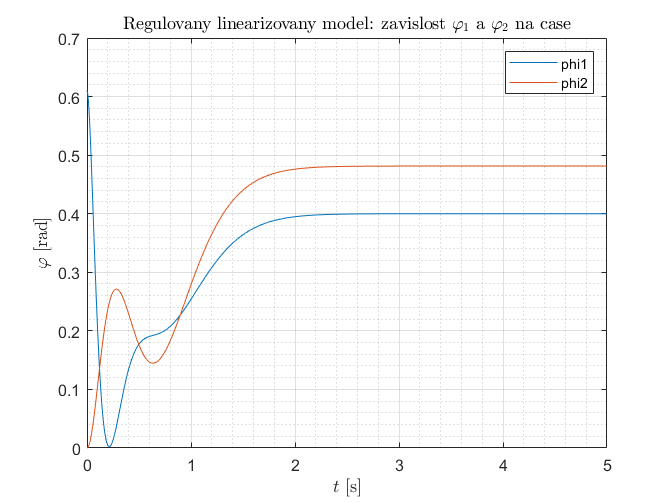

figure
plot(phi1_lin_rx)
hold on %podrží graf na obrazovce, aby mohl být přidán další
plot(phi2_lin_rx)
grid on %zapne mřížku grafu
grid minor %zapne přesnější mřížku
title('Regulovany linearizovany model: zavislost $$\varphi_1$$ a $$\varphi_2$$ na case','Interpreter','latex') %nadpis grafu
xlabel('$t$ [s]','Interpreter','latex') %popis osy x
ylabel('$\varphi$ [rad]','Interpreter','latex') %popis osy y
legend({'phi1','phi2'},'Location','northeast') %legenda grafu

#### Animace

Pomocí tlačítka "Spustit animaci" se spustí animace pohybu kyvadel regulovaného linearizovaného systému, který má dospět do požadovaného konečného stavu $\varphi_{1k} = x_{1k}$. 

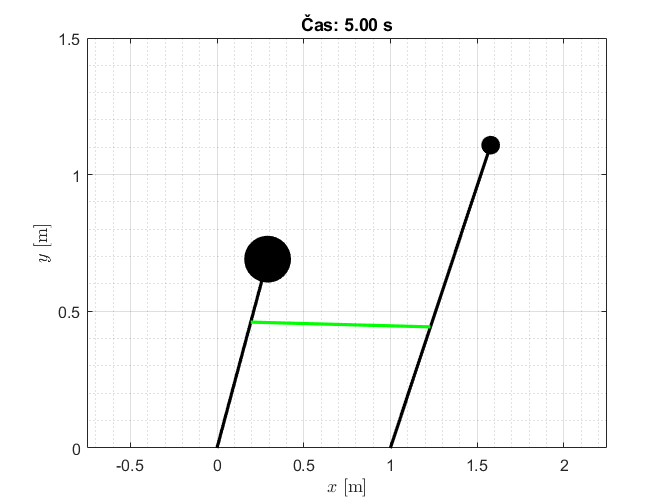

 
%close all
figure
%plot(0,0)
%grid on


for i = 1:length(phi1_lin_rx.Data)
    cla
    
    %kyvadlo 1
    plot([0 b*sin(phi1_lin_rx.Data(i))],[0 b*cos(phi1_lin_rx.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 1 tyč
    hold on
    plot(b*sin(phi1_lin_rx.Data(i)),b*cos(phi1_lin_rx.Data(i)),'MarkerSize',m1*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 1 závaží
    
    %kyvadlo 2 
    hold on
    plot(d+[0 c*sin(phi2_lin_rx.Data(i))],[0 c*cos(phi2_lin_rx.Data(i))],'LineWidth',2,"Color",[0 0 0]) %kyvadlo 2 tyč
    hold on
    plot(d+c*sin(phi2_lin_rx.Data(i)),c*cos(phi2_lin_rx.Data(i)),'MarkerSize',m2*20,'Marker','.','LineWidth',2,"Color",[0 0 0]); %kyvadlo 2 závaží
    
    %pružina
    hold on
    if((phi1_lin_rx.Data(i)-phi2_lin_rx.Data(i))>=0)
        plot([a*sin(phi1_lin_rx.Data(i)) (d+a*sin(phi2_lin_rx.Data(i)))],[a*cos(phi1_lin_rx.Data(i)) a*cos(phi2_lin_rx.Data(i))],'LineWidth',2,"Color",[1 0 0]) % kyvadlo 1 tyč
    else
        plot([a*sin(phi1_lin_rx.Data(i)) (d+a*sin(phi2_lin_rx.Data(i)))],[a*cos(phi1_lin_rx.Data(i)) a*cos(phi2_lin_rx.Data(i))],'LineWidth',2,"Color",[0 1 0]) % kyvadlo 1 tyč
    end
    
    
    %nastavení rozsahů os
    xlim([-b (d+c)])
    ylim([0 c*1.2])
    
    
    
    %popis grafu
    title(['Čas: ',num2str(phi1.Time(i),'%1.2f'),' s']) %nadpis grafu
    xlabel('$x$ [m]','Interpreter','latex') %popis osy x
    ylabel('$y$ [m]','Interpreter','latex') %popis osy y
    grid on %zapne mřížku grafu
    grid minor %zapne přesnější mřížku
    
    %nastavení rychlosti animace
    pause(.0001)
    %zobrazení reálného času
    %legend(,'Location','northeast') %legenda grafu
end